# Calibration

clc;
clear;
clf;

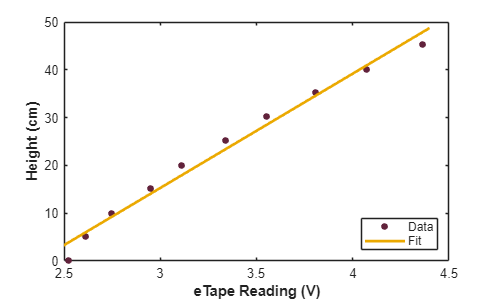

% Calibration data for eTape 1
height = [0, 5.1, 10, 15.1, 20, 25.2, 30.2, 35.3, 40.1, 45.3]; % cm
level = (5/1023).*[516, 534.5, 562.5, 603.5, 636.5, 683.5, 726.5, 778.5, 832.5, 893]; % volts

p1 = polyfit(level, height, 1);
x1 = (5/1023).*linspace(500, 900, 10);
y1 = polyval(p1, x1);


% plot everything
f1 = figure(1);
plot(level, height, ".", "MarkerSize", 15, "Color", "#61223b")
xlabel("eTape Reading (V)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
hold on
plot(x1, y1, "Color", "#eba900", "LineWidth", 2)
legend("Data", "Fit", Location="southeast")
xlim([2.5 4.5])
ylim([0 50])
hold off


s1 = sprintf("h = %.1f x + %.1f", p1(1), p1(2))

s1 = "h = 23.9 x + -56.5"


% export figure 1 at a 600 DPI resolution (commented out when not needing
% to export)
% exportgraphics(f1, "Calibration_Curve.png", "Resolution", 600, "Padding", "figure")

% calculating statistical values to determine the best fit
n = 10;
SSE1 = sum((height - y1).^2);

TSS = sum((height - mean(height)).^2);

R21 = 1 - SSE1/TSS

R21 = 0.9633


R2a1 = 1 - ((n - 1)/(n - 2)).*(SSE1/TSS)

R2a1 = 0.9587

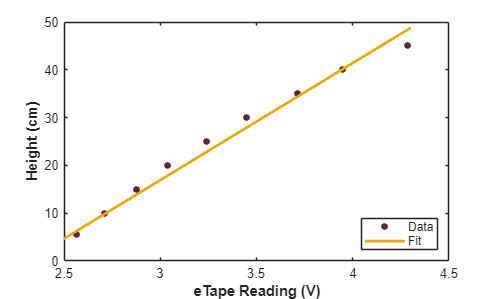

% Calibration data for eTape 2
height2 = [0, 5.5, 10, 15, 20, 25.1, 30.1, 35.1, 40, 45]; % cm
level2 = (5/1023).*[508, 525, 555, 589, 621, 663, 706, 760, 807, 877]; % volts

p2 = polyfit(level2, height2, 1);
x2 = (5/1023).*linspace(500, 880, 10);
y2 = polyval(p2, x2);

% plot everything
f2 = figure(2);
plot(level2, height2, ".", "MarkerSize", 15, "Color", "#61223b")
xlabel("eTape Reading (V)", "FontWeight", "bold")
ylabel("Height (cm)", "FontWeight", "bold")
hold on
plot(x2, y2, "Color", "#eba900", "LineWidth", 2)
legend("Data", "Fit", Location="southeast")
xlim([2.5 4.5])
ylim([0 50])


s2 = sprintf("h = %.1f x + %.1f", p2(1), p2(2))

s2 = "h = 24.5 x + -56.6"

% calculating statistical values to determine the best fit
n = 10;
SSE2 = sum((height2 - y2).^2);

TSS2 = sum((height2 - mean(height2)).^2);

R22 = 1 - SSE2/TSS2

R22 = 0.9413


R2a2 = 1 - ((n - 1)/(n - 2)).*(SSE2/TSS2)

R2a2 = 0.9340